Take the function y = sin(x 2 ) for x = 0 : 0.05 : 3π and try to approximate it using a neural network with one hidden layer. Use different algorithms. How does gradient descent perform compared to other training algorithms?

clear
clc
close all

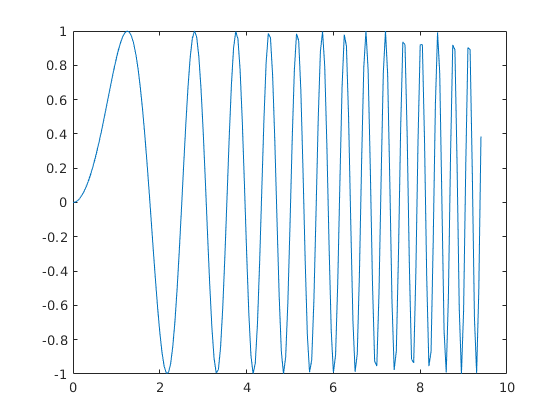

x = 0:0.05:3*pi; y = sin(x.^2);
p=con2seq(x); t=con2seq(y);
plot(x,y)

net1=feedforwardnet(50,'traingd'); %initialising feedforward networks with 50 neurons
net2=feedforwardnet(50,'traingda');
net3=feedforwardnet(50,'traincgf');
net4=feedforwardnet(50,'traincgp');
net5=feedforwardnet(50,'trainbfg');
net6=feedforwardnet(50,'trainlm');


net2.iw{1,1}=net1.iw{1,1};  %set the same weights for the networks 
net2.lw{2,1}=net1.lw{2,1};
net3.iw{1,1}=net1.iw{1,1};   
net3.lw{2,1}=net1.lw{2,1};
net4.iw{1,1}=net1.iw{1,1};   
net4.lw{2,1}=net1.lw{2,1};
net5.iw{1,1}=net1.iw{1,1};  
net5.lw{2,1}=net1.lw{2,1};
net6.iw{1,1}=net1.iw{1,1};   
net6.lw{2,1}=net1.lw{2,1};

net2.b{1}=net1.b{1};   %set the same biases for the networks 
net2.b{2}=net1.b{2};
net3.b{1}=net1.b{1};
net3.b{2}=net1.b{2};
net4.b{1}=net1.b{1};
net4.b{2}=net1.b{2};
net5.b{1}=net1.b{1};
net5.b{2}=net1.b{2};
net6.b{1}=net1.b{1};
net6.b{2}=net1.b{2};

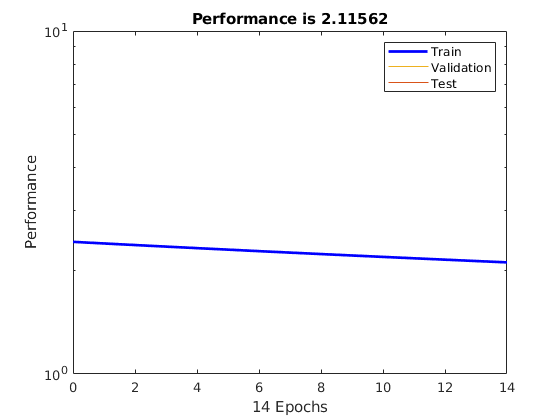

%training and simulation

%1 Epoch
net1.trainParam.epochs=1;  % set the number of epochs for the training 
net2.trainParam.epochs=1;
net3.trainParam.epochs=1;
net4.trainParam.epochs=1;
net5.trainParam.epochs=1;
net6.trainParam.epochs=1;

net1=train(net1,p,t);   % train the networks
net2=train(net2,p,t);
net3=train(net3,p,t);
net4=train(net4,p,t);
net5=train(net5,p,t);
net6=train(net6,p,t);

a11=sim(net1,p);     % simulate the networks with the input vector p
a21=sim(net2,p);
a31=sim(net3,p);
a41=sim(net4,p);
a51=sim(net5,p);
a61=sim(net6,p);

% 14 Epochs
net1.trainParam.epochs=14;
net2.trainParam.epochs=14;
net3.trainParam.epochs=14;
net4.trainParam.epochs=14;
net5.trainParam.epochs=14;
net6.trainParam.epochs=14;

[net1, tr1] = train(net1,p,t);
plotperf(tr1);

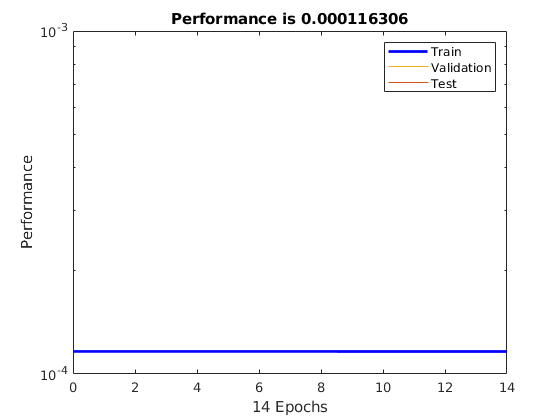

[net2, tr2]=train(net2,p,t);
plotperf(tr2);
[net3, tr3]=train(net3,p,t);
plotperf(tr3);
[net4, tr4]=train(net4,p,t);
plotperf(tr4);
[net5, tr5]=train(net5,p,t);
plotperf(tr5);

[net6, tr6]=train(net6,p,t);
plotperf(tr6);

Conversion to logical from matlab.ui.Figure is not possible.

Error in plotperf (line 55)
  if (fig), delete(fig); end


a12=sim(net1,p);
a22=sim(net2,p);
a32=sim(net3,p);
a42=sim(net4,p);
a52=sim(net5,p);
a62=sim(net6,p);

% 985 Epochs
net1.trainParam.epochs=985;
net2.trainParam.epochs=985;
net3.trainParam.epochs=985;
net4.trainParam.epochs=985;
net5.trainParam.epochs=985;
net6.trainParam.epochs=985;

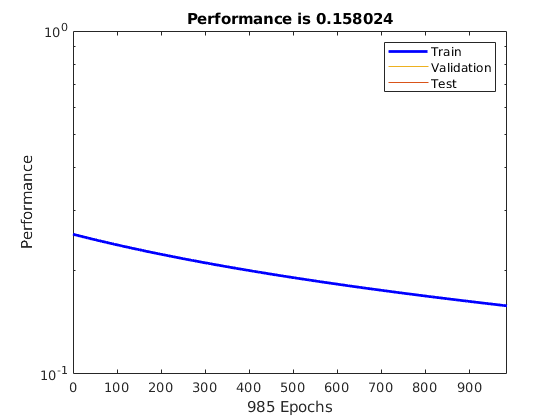


[net1, tr1] = train(net1,p,t);
plotperf(tr1);

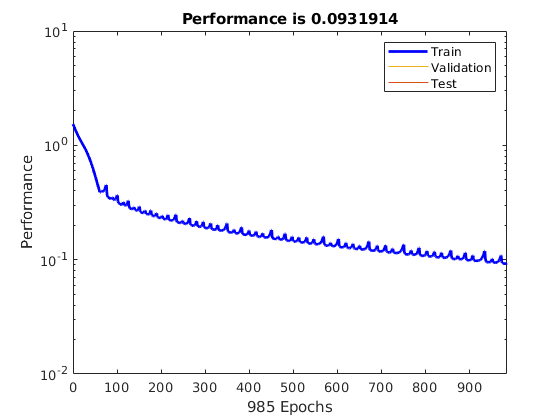

[net2, tr2] =train(net2,p,t);
plotperf(tr2);
net3=train(net3,p,t);
net4=train(net4,p,t);

net5=train(net5,p,t);
net6=train(net6,p,t);

a13=sim(net1,p);
a23=sim(net2,p);
a33=sim(net3,p);
a43=sim(net4,p);
a53=sim(net5,p);
a63=sim(net6,p);

r11 = abs(regression(cell2mat(a11),y));
r21 = abs(regression(cell2mat(a21),y));
r31 = abs(regression(cell2mat(a31),y));
r41 = abs(regression(cell2mat(a41),y));
r51 = abs(regression(cell2mat(a51),y));
r61 = abs(regression(cell2mat(a61),y));

r12 = abs(regression(cell2mat(a12),y));
r22 = abs(regression(cell2mat(a22),y));
r32 = abs(regression(cell2mat(a32),y));
r42 = abs(regression(cell2mat(a42),y));
r52 = abs(regression(cell2mat(a52),y));
r62 = abs(regression(cell2mat(a62),y));

r13 = abs(regression(cell2mat(a13),y));
r23 = abs(regression(cell2mat(a23),y));
r33 = abs(regression(cell2mat(a33),y));
r43 = abs(regression(cell2mat(a43),y));
r53 = abs(regression(cell2mat(a53),y));
r63 = abs(regression(cell2mat(a63),y));


perf1 = perform(net1, a11, t);

perf1 = 0.2366

perf2 = perform(net1, a21, t);

perf2 = 0.0885

perf3 = perform(net1, a31, t);
perf4 = perform(net1, a41, t);
perf5 = perform(net1, a51, t);
perf6 = perform(net1, a61, t);

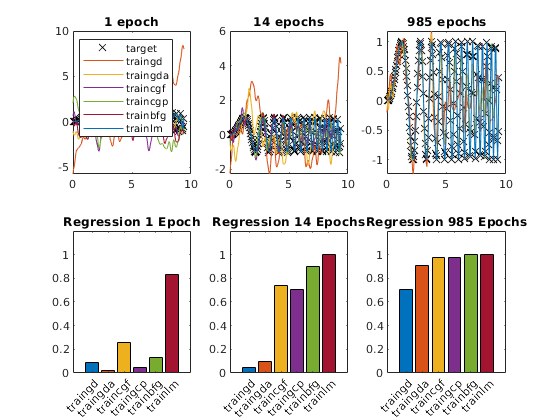

%Plotting
newcolours = [0 0.4470 0.7410
              0.8500 0.3250 0.0980
              0.9290 0.6940 0.1250
              0.4940 0.1840 0.5560
              0.4660 0.6740 0.1880
              0.6350 0.0780 0.1840];

algorithm = {'traingd'; 'traingda'; 'traincgf'; 'traingcp'; 'trainbfg'; 'trainlm'};
regress_1 = [r11 r21 r31 r41 r51 r61];
regress_14 = [r12 r22 r32 r42 r52 r62];
regress_985 = [r13 r23 r33 r43 r53 r63];

figure
subplot(2,3,1);
plot(x,y,'kx',x,cell2mat(a11),x,cell2mat(a21), x,cell2mat(a31),x,cell2mat(a41), ...
    x,cell2mat(a51),x,cell2mat(a61)); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','traingd','traingda', 'traincgf','traincgp','trainbfg','trainlm','Location','northwest');

subplot(2,3,2);
plot(x,y,'kx',x,cell2mat(a12),x,cell2mat(a22), x,cell2mat(a32),x,cell2mat(a42),...
    x,cell2mat(a52),x,cell2mat(a62)); % plot the sine function and the output of the networks 
title('14 epochs');
legend('target','traingd','traingda', 'traincgf','traincgp','trainbfg','trainlm','Location','north');
legend('off')

subplot(2,3,3);
plot(x,y,'kx',x,cell2mat(a13),x,cell2mat(a23), x,cell2mat(a33),x,cell2mat(a43), ...
    x,cell2mat(a53),x,cell2mat(a63)); % plot the sine function and the output of the networks
title('985 epochs');
legend('target','traingd','traingda', 'traincgf','traincgp','trainbfg','trainlm','Location','north');
legend('off')

subplot(2,3,4);
b = bar(regress_1,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.2]);
title('Regression 1 Epoch');

subplot(2,3,5);
b = bar(regress_14,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.2]);
title('Regression 14 Epochs');

subplot(2,3,6);
b = bar(regress_985,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.2]);
title('Regression 985 Epochs');

colororder(newcolours);